# Simulation of HHG via TDSE

## Initialisation

clear;
Proj = currentProject;
ENERGY = @(l) (1e9*Constants.h*Constants.c/Constants.e)./l;

AXIS = @(N) ((0:N-1).'-floor(N/2))

AXIS = function_handle with value:
    @(N)((0:N-1).'-floor(N/2))

NORM = @(y, dim) y./max(y, [], dim);
F2S = @(psi) Freq2Space(psi);
S2F = @(psi) Space2Freq(psi);

TPAD = 4;
WPAD = 1.5;
XPAD = 5;
TOL = 1e-6;

### Pulse Parameters

Ip = 15.7596;			%	[eV]
DT = 10;				%	FWHM [fs]
l0 = 800;				%	[nm]
w0 = Convert_wl(l0);	%	[rad/fs]
T = 2*pi/w0;			%	[fs]
I0 = 500;				%	[TW/cm^2]
E0 = sqrt(2e16*I0/(Constants.eps_0*Constants.c));	%	[V/m] 

T_au = Constants.SItoAU("Time", T*1e-15);
w0_au = 2*pi/T_au;
w0_eV = ENERGY(l0);
DT_au = Constants.SItoAU("Time", DT*1e-15);
E0_au = Constants.SItoAU("ElectricField", E0);
Ip_au = Constants.SItoAU("Energy", Ip*Constants.e);

Up = 1e-7*I0*l0.^2;
wmax = WPAD*Convert_wl(ENERGY(Ip + 3.2*Up));

Nt = 2^nextpow2(floor(wmax*DT*TPAD/pi))

Nt = 4096

dt = TPAD*DT/(Nt-1);
dw = 2*pi/(Nt*dt);
t = AXIS(Nt)*dt;
w = (0:Nt-1).'*dw;
q = w/w0;
l = Convert_wl(w);
w_eV = ENERGY(l);
t_au = Constants.SItoAU("Time", t*1e-15);

%	Units in a.u.
xmax = 2*E0_au/w0_au^2;
dx = pi*w0_au/(sqrt(5)*E0_au);
Nx = 2^nextpow2(XPAD*2*xmax/dx);
dx = dx/4;
dkx = 2*pi/(Nx*dx);
x = AXIS(Nx)*dx;
kx = AXIS(Nx)*dkx;

%	Gradient functions
D = spdiags(ones(Nx, 1).*(.5*[-1 1]/dx), [-1 1], Nx, Nx);
D(1, 1:3) = .5*[-3 4 -1]/dx;
D(end, end-2:end) = .5*[-1 4 -3]/dx;
D2 = spdiags(ones(Nx, 1).*([1 -2 1]/dx^2), -1:1, Nx, Nx);

x_nm = 1e9*Constants.AUtoSI("Length", x);

### Ground State

U = @(s) -(x.^2 + s.^2).^-.5;
s = fzero(@(s) eigs(-.5*D2 + spdiags(U(s), 0, Nx, Nx), 1, -2/s)+Ip_au, [.1 10]);
U0 = U(s);

[psi0, En] = eigs(-.5*D2 + spdiags(U0, 0, Nx, Nx), 3, -2*Ip_au);
psi0 = psi0(:, end);

## TDSE

### Absorbing barrier

n = (0:Nx-1).';
dn = Nx/8;
Vbar = -20i*( ((dn-n)/dn).^2.*(n<dn) + ((Nx-dn-n-1)/dn).^2.*(n>=Nx-dn) );
% Vbar = Vbar + 1e-5i./U0;
% Vbar = Vbar - 1e-4i*exp(-10*psi0/max(psi0));


### Operators

ET = @(t) E0_au*gauss1D(t, 0, sqrt(2)*DT_au, 1).*cos(w0_au*t);
VT = @(t, dt) exp(-.5i*(Vbar + U0 + ET(t)*x)*dt);
TT = @(dt) exp(-.5i*kx.^2*dt);

psi = zeros(Nx, Nt, "like", 1i);
psi(:, 1) = psi0;
nt = 2;
tn = t_au(1);
dt = .5;
multiWaitbar('TDSE', 'Value', 1/Nt);
while tn<t_au(end)
	[psi1, dt1] = AdaptiveSplitStep(tn, psi0, VT, TT, dt, TOL);
	tn = tn+dt;
	if tn>=t_au(nt)
		psi(:, nt) = psi0 + (tn-t_au(nt))*(psi1-psi0)/dt;
		nt = nt+1;
		multiWaitbar('TDSE', 'Increment', 1/Nt);
	end
	dt = dt1;
	psi0 = psi1;
end
multiWaitbar('CloseAll');

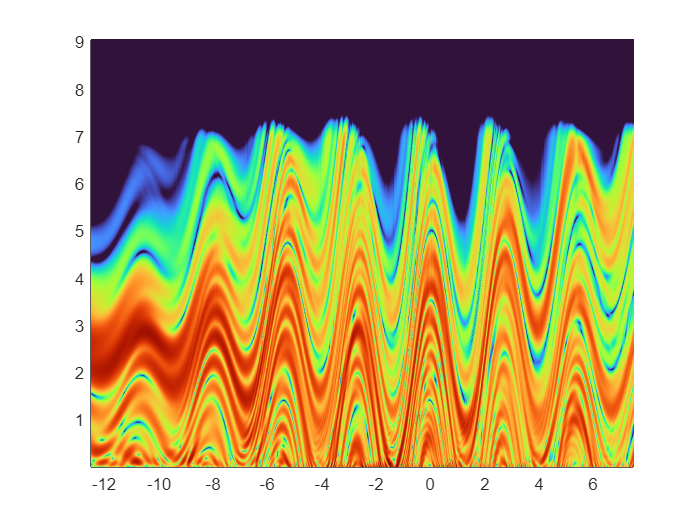

indt = abs(t+DT/4)<DT;
indx = (x>0) & mod(x, 2);
h = pcolor(t(indt), x_nm(indx), log10(abs2(psi(indx, indt))));
h.LineStyle = "None";
grid on;
grid minor;
colormap turbo
clim([-6 log10(max(abs2(psi), [], "all"))]);

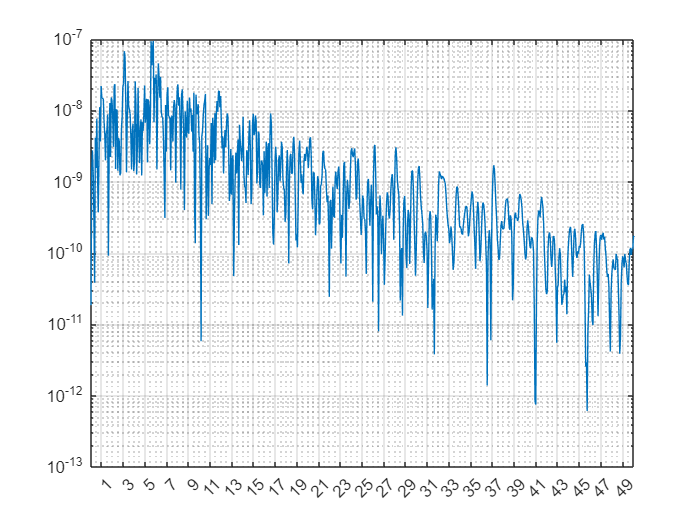

semilogy(q, abs2(Time2Freq(sum(abs2(psi).*(D*U0))))); 
xticks(1:2:q(end)); 
grid on; 
grid minor;
xlim([0 50]);

## Functions

function [psi, dt, err] = AdaptiveSplitStep(t, psi, V, T, dt, tol)
err = inf;
while err>tol
	T1 = T(dt);
	V1 = V(t, dt);
	V2 = V1.^2;
	psi1 = V1.*Freq2Space(T1.*Space2Freq(V1.*psi));
	psi2 = Freq2Space(T1.*Space2Freq(V2.*psi));
	err = sum(abs2(psi2-psi1))/sum(abs2(psi));
	dt = .9*dt*min(max(sqrt(.5*tol/err), .3), 2);
end
psi = psi1;
end